Check whether LTV nlMPC works on FD_Eul plant and model for each trajectory. Get controller hyperparameters.

%Specify State dims, output dims and input dims,
nx = 12;
ny = 12;
nu = 8;

%Set model and plant
model = @TiltrotorDiscrete_model;
%model = @TiltrotorDiscrete_model_Perturbed;
plant = @TiltrotorPlant_fd_Eul;

%create nmpc object
nlobj = nlmpc(nx, ny, nu);

In standard cost function, zero weights are applied by default to one or more OVs because there are fewer MVs than OVs.



%setup nlobj 
nlobj.Model.StateFcn = model; 
nlobj.Model.IsContinuousTime = false;
nlobj.Model.NumberOfParameters = 1;

%sample time
Ts = 0.1;
%Prediction_horizon
p = 10;
%input horizon
m = 1;

% Set parameters to nmpc
nlobj.Ts = Ts;
nlobj.PredictionHorizon = p;
nlobj.ControlHorizon = m;

%input constraints (rad/s) ^2 and rads
nlobj.MV = struct('Min',{0;0;0;0;-pi;-pi;-pi;-pi},...
                  'Max',{1000;1000;1000;1000;pi;pi;pi;pi});

%1000 rad/s ~=10000 RPM which is sensible

% Tracking costs
nlobj.Weights.OutputVariables = 10*[1 1 1 1 1 1 0 0 0 0 0 0];

%To prioritize targets, set the average MV tracking priority lower than the average OV tracking priority.
%weights on motor input costs correspond to propeller thrust coefficient
%weights on tilt input costs represent the relatively low cost of tilting
%compared to propeller thrust.
nlobj.Weights.ManipulatedVariables = [8e-5 8e-5 8e-5 8e-5 ...
                                      0.1 0.1 0.1 0.1];

% penalize aggressive control actions by specifying tuning weights for the MV rates of change.
%
nlobj.Weights.ManipulatedVariablesRate = [0.1 0.1 0.1 0.1 ...
                                          0.5 0.5 0.5 0.5];

nlobj.Optimization.RunAsLinearMPC='TimeVarying';
                                      
%% Closed Loop Simulation for duration
% Specify the initial state
x = [0;0;0;0;0;0;0;0;0;0;0;0];
s0 = zeros(20,1);

nloptions = nlmpcmoveopt;
nloptions.Parameters = {Ts} ;

%validate model
rng(0)
validateFcns(nlobj,rand(nx,1),rand(nu,1),[],{Ts});

Model.StateFcn is OK.
No output function specified. Assuming "y = x" in the prediction model.
Analysis of user-provided model, cost, and constraint functions complete.


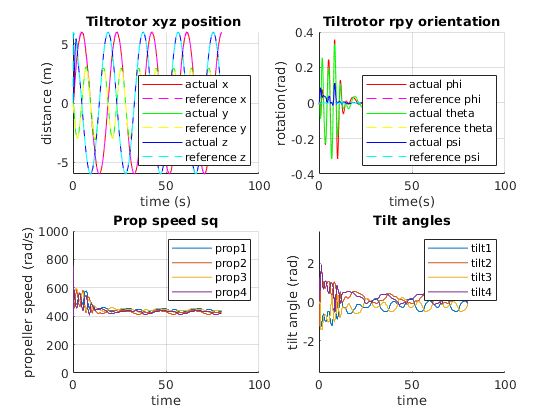


%input reference
nloptions.MVTarget = [0 0 0 0 0 0 0 0]; 
mv = [400 400 400 400 0 0 0 0];

Duration = 80;

xHistory = x';
sHistory = s0';

xpredHistory = zeros(size(x'));

xdotHistory = zeros(size(x')); 
xdotpredHistory = zeros(size(x'));

xdotnnpredHistory = zeros(size(x'));

yrefHistory = zeros(size(x'));

lastMV = mv;
uHistory = lastMV;

costs = zeros(Duration/Ts,1);
elapsed_times = zeros(Duration/Ts,1);

%set trajectory
trajectories = {@LoopTrajectory}; %@RotxTrajectory @DataTrajectory @ComplexTrajectory @LoopTrajectory @SinzTrajectory};

%set disturbance
F_dist = @no_dist;

for l=1:length(trajectories)
hbar = waitbar(0,'Simulation Progress');
trajectory = trajectories{l};

for m = 1:(Duration/Ts)
    k = (l-1)*Duration/Ts+m;
    % Set references for previewing
    t = linspace(k*Ts, (k+p-1)*Ts,p);
    
    yref = trajectory(t);
    yrefHistory(k+1,:) = yref(:,1)';
    % Compute the control moves with reference previewing.
    xk = xHistory(k,:);
    sk = sHistory(k,:);
 
    tic;
    [uk,nloptions,info] = nlmpcmove(nlobj,xk,lastMV,yref',[],nloptions);
    elapsed_times(k) = toc;

    uHistory(k+1,:) = uk';
    lastMV = uk;
    
    % Update states.
    ODEFUN = @(t,sk) plant(sk,uk,F_dist(xk,uk));
    [TOUT,YOUT] = ode45(ODEFUN,[0 Ts], sHistory(k,:)');
    sHistory(k+1,:) = YOUT(end,:);

    xHistory(k+1,:) = sHistory(k+1,1:12);
    costs(k+1)=info.Cost;
    waitbar(m*Ts/(Duration),hbar);
    
end
close(hbar)

end
time = 0:Ts:length(trajectories)*Duration;
yreftot = trajectory(time)';
plothistories(time,xHistory,yrefHistory,uHistory);

% Passed all trajectories